# Tutorial: Plot customizations

The information in `Individual` objects can be displayed graphically in different ways. In this tutorial, you will learn how to produce customized plots in the MATLAB PBPK toolbox. 

#### Example simulation results for plotting

First, we will create an `Individual` array to display graphically. We use two virtual individuals here, both dosed with lidocaine, once orally, and once as an iv infusion, and simulate a PBPK model for a male adult for both.

obs = PBPKobservables();

indv = Individual(2,'Virtual');

indv(1).name = 'Lidocaine (oral)';
indv(1).dosing     = Oral('Lidocaine', 0*u.h, 100*u.mg);
indv(1).drugdata   = loaddrugdata('Lidocaine','species','human');
indv(1).physiology = Physiology('human35m');
indv(1).sampling   = Sampling([0 24]*u.h, obs);
indv(1).model      = sMD_PBPK_12CMT_wellstirred;
indv(1).model.options.tissuePartitioning = @rodgersrowland;

indv(2) = clone(indv(1));
indv(2).name = 'Lidocaine (iv infusion)';
indv(2).dosing = Infusion('Lidocaine', 0*u.h, 100*u.mg, 1*u.h, 'iv');

initialize(indv)
simulate(indv)

Once the simulation is finished, we can have a look at these two individuals:

indv(1)

ans = 	Individual object:

           type: 'Virtual individual'
           name: 'Lidocaine (oral)'
         dosing: '1 Oral event(s)'
     physiology: '35 parameters defined'
       sampling: 'timespan 0 h - 24 h with 11 observables'
       drugdata: '14 parameters defined'
    observation: '3993 records'

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

indv(2)

ans = 	Individual object:

           type: 'Virtual individual'
           name: 'Lidocaine (iv infusion)'
         dosing: '1 Infusion event(s)'
     physiology: '35 parameters defined'
       sampling: 'timespan 0 h - 24 h with 11 observables'
       drugdata: '14 parameters defined'
    observation: '5929 records'

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

Now we want to display information from this simulation graphically.

#### Default plots

By default, function `plot()` produces two plots, first, plasma concentration-time profiles, and second, concentration-time profiles in 10 tissues: 

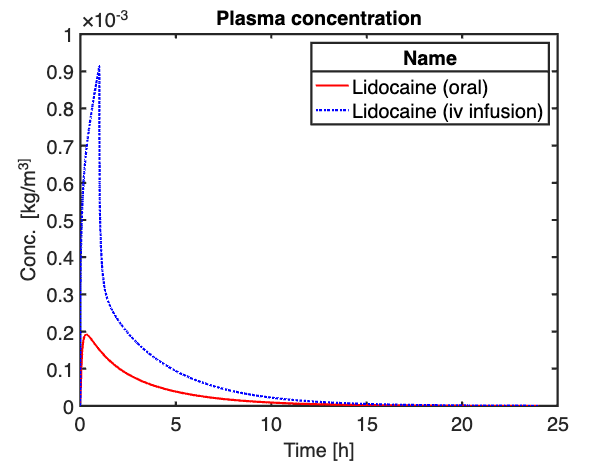

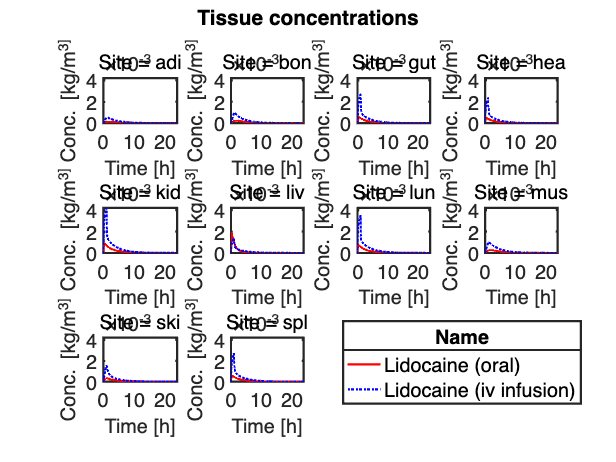

plot(indv)

If we want to customize these plots, the starting point is to look at function `plottemplate()`, where these two default plots are defined, and which is called from the `plot()` method of the `Individual` class.

Function `plottemplate()` consists of a short main function and several subfunctions. Each subfunction corresponds to one type of plot. Four subfunctions are defined:

- `plasmaConcentration()`;

- `allTissues()`;

- `massBalance()` and 

- `percentilesPlasmaConc()`. 

Going back up to the main function, you can see that handles to two of these functions are stored in variable `defaultplots`. These are the two plots that we just produced. You can also see a "`type`" argument to `plottemplate()`. Any of the subfunctions can be provided as argument "`type`", whether it's a default plot or not. We can also call the plotting function with one of these types, for example, to produce the first of the two default plots:

plot(indv,'plasmaConcentration')

#### Customize a plot

To customize plot behaviour, you can use a lower-level plotting function rather than calling the plot function it self, as is done in the subfunctions of the plottemplate. This requires that we take a closer look at the structure of such a subfunction and the lower-level plotting functions.

Subfunction `plasmaConcentration()` calls another function `longitudinalplot()` with a lot of arguments. Calling this functions with different arguments results in different information from the `Individual` array to be extracted and displayed graphically. The first three of the four subfunctions all use a different call to `longitudinalplot()`. The last subfunction, `percentilesPlasmaConc()`, calls another lower-level plotting function, called `percentileplot()`, which has the same syntax as `longitudinalplot()` but produces a different plot.

The syntax of these lower-level plotting functions is as follows. After the first argument `individual`, they accept a large number of name-value pairs, that is, pairs of arguments of which the first specifies the name of the property to be edited, and the second its value. We can consult the function help for a complete list of supported properties:

help longitudinalplot

 longitudinalplot Plotting function for longitudinal data
    longitudinalplot(INDIVIDUAL) produces an observable-time plot for the
    Individual object (array) INDIVIDUAL, with default options.
 
    longitudinalplot(INDIVIDUAL,NM1,VAL1,NM2,VAL2,...) uses plot options 
    specified as name-value pairs NM1,VAL1,NM2,VAL2,... (see below)
 
    H = longitudinalplot(...) returns the handle to the plot.
 
    TAB = longitudinalplot(INDIVIDUAL, 'tableOutput', true, ...) returns an
    aggregated table that can be used for customized plotting if there is
    need for more control over the plots. Of the additional arguments (...)
    provided, only 'obs' will impact (=subsetting TAB) on the output. No
    figure will be drawn.
 
    The following plot options are defined:
 
    Parameter        Explanation                Default         
    ---------        -----------                -------
    tunit      

This also contains a detailed explaination of each property, and how to specify it. The most important properties for us are "`subplot_by`" and "`group_by`", which stratify the data according to a particular criterion.

In the default plots of the plottemplate, a subplot per site is produced, and data are grouped by names of the individuals. Grouping means that within each group, the same plotting color and style are used. In addition, for virtual individuals connected lines are used. Other options for subplotting or grouping are per ID, that is, the numerical index of the individual in the Individual array, or per type of ID, experimental or virtual. You can also use any attribute of the Observable class, such as "`Site`".

Finally, any arguments to the lower-level plotting function can be specified as additional name-value pairs to the `plot()` call. For example, you can specify time and concentration units for all default plots:

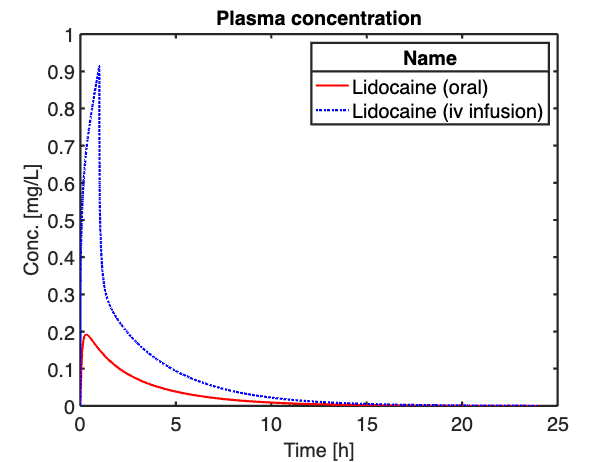

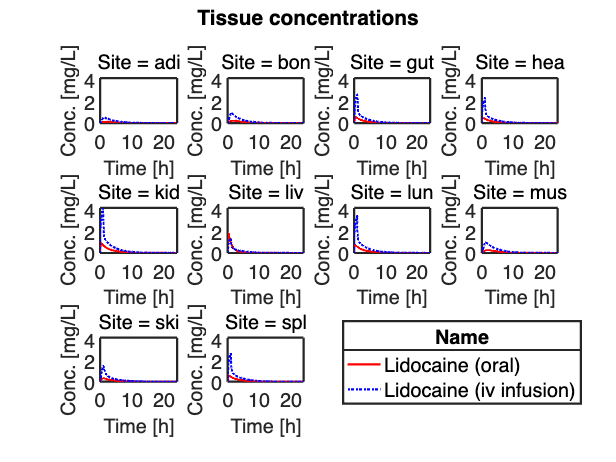

plot(indv, 'tunit', 'h', 'yunit', 'mg/L')

or just for the plasma concentration plot:

plot(indv, 'plasmaConcentration', 'tunit', 'h', 'yunit', 'mg/L')

You can also produce the same plot by calling function `longitudinalplot()` itself:

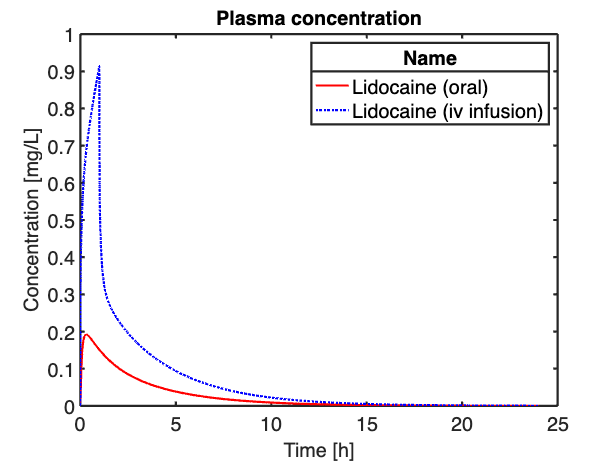

longitudinalplot(indv, ...
    'Site',     'pla', ...
    'group_by', 'Name', ...
    'xlabel',   'Time', ...
    'ylabel',   'Concentration', ...
    'title',    'Plasma concentration', ...
    'tunit',    'h', ...
    'yunit',    'mg/L')

#### Exercise

Here's a small exercise to practice customizing plots. Imagine you want to create the following plot from the `Individual` array considered before:

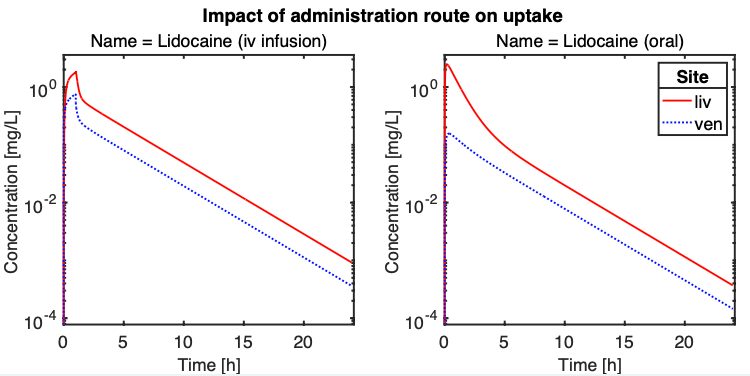

What are the customization settings of the toolbox plot to produce this plot?

*(Note: after customization, the Zoom in the MATLAB Figure explorer was also used)*

Try to do the computation in the toolbox; you can check your result in the `solution_tutorials` file.